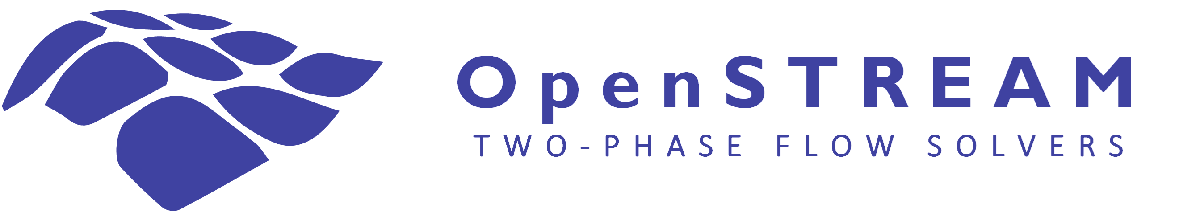

# Tutorial #1: Basic capabilities and functionalities

## Introduction

Welcome to OpenSTREAM!

In this tutorial, you will learn how to use the basic features of the code, with provided examples to run a simple case using all four solvers.

The selected geometry consists of a 3.5 m uniformly heated vertical tube with an inner diameter of 8.8 mm, followed by a 2 m adiabatic section (of same diameter). The flow enters slightly subcooled, transitions to annular two-phase flow around 0.7 m, and reaches the critical boiling transition (film dryout) at the end of the heated section. In the adiabatic region, droplets deposit on the wall, regenerating the liquid film at the wall and leading to a fully developed annular flow.

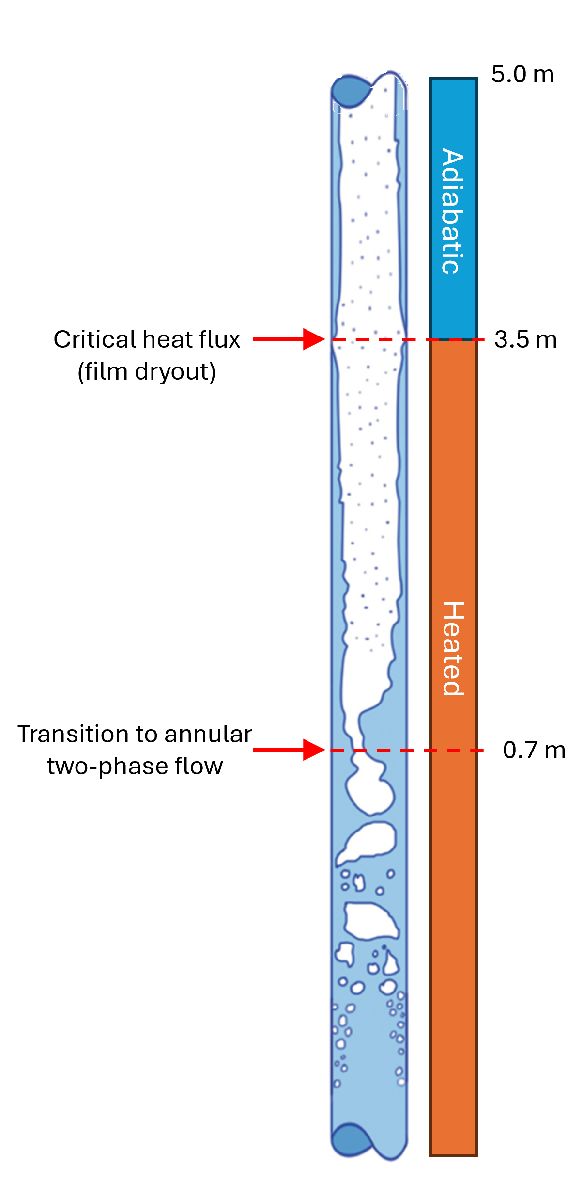

% Clear existing variables from workspace
clearvars

Before starting this tutorial, make sure OpenSTREAM is included in your MATLAB search path. If you are running the tutorial directly from the `tutorials` folder, you can add OpenSTREAM like this:

% Add path to OpenSTREAM
osp = './..';                      % When running from the tutorials folder
addpath(osp);

## Input files

All the input files you will need for this tutorial are already provided in the `openstream/inputs/` folder.

We first start by adding the inputs and solver packages to the import list. 

% Import the inputs and solvers packages
import Inputs.*
import Solvers.*

The `Inputs` package defines a set of classes used to configure and import all the necessary parameters for running OpenSTREAM simulations. The `Solvers` package defines the OpenSTREAM core solver modules and their associated superclasses. 

The path to the physical models, numerical options, test section geometry and boundary condition files are provided and read by `InputSet` as shown below. Since each file can include various set of inputs (several geometries, etc.), the `ID`s corresponding to the relevant sets must be indicated. New user-specific files can be created and the paths can be modified by the user, based on the specific working directory and file locations.

The models and options parameters not specified in the input files are set to their default values listed [here](https://openstream-solvers.github.io/openstream/Packages/Inputs.html). 

% Turn off warnings during input setup
warning off
% Create the input set using paths to model, options, geometry, and boundary condition files
inputSet = InputSet( ...
            modelFilePath         = [osp '/inputs/models.inp'] , modelID    = 'TUTORIAL1', ...
            optionsFilePath       = [osp '/inputs/options.inp'], optionsID  = 'DEFAULT'  , ...
            geometryFilePath      = [osp '/inputs/geom.inp']   , geometryID = 'TUTORIAL1', ...
            bcFilePath            = [osp '/inputs/tutorial1.inp'], ...
            sessionParentDir      = fullfile(pwd,'outputs')       , ...
            overwriteSessionFiles = true                         , ...
            LOGMODE               = 'BOTH');
% Turn off warnings during input setup
warning on

Note:

- Turning on the warning will print the set defaults values to the prompt.

- `LOGMODE` can be set to `'LOGTOFILEONLY'` to suppress (almost) all print outputs when running OpenSTREAM.

We can examine the physical model inputs by opening the `models.inp` file or using the command below, then scroll to locate the `ID` entries labeled `TUTORIAL1`.

type('../inputs/models.inp')

This indicates that the simulations will use 100 nodes and that water is the working fluid.

Model inputs are mostly solver-specific and can be reviewed (along with the default models) at the following [link](https://openstream-solvers.github.io/openstream/Packages/Inputs.html#Inputs.Model). Note that each model is organized by solver within the `Inputs.Model` class definition file.

A simple and self-explanatory input file format has been defined for use with OpenSTREAM, as shown above (note that any input between `!` and `>` is treated as a comment). Alternatively, a JSON file format can also be used if preferred.

type('../inputs/models.json')

We can examine the numerical option inputs by opening the `options.inp` file or using the command below, then scroll to locate the `ID` entry labeled `DEFAULT`.

type('../inputs/options.inp')

Note that no specific options have been defined, i.e., defaults setting are used for the simulations.

Options inputs are mostly solver-specific and can be reviewed (including the default options) at the following [link](https://openstream-solvers.github.io/openstream/Packages/Inputs.html#Inputs.Options).

We can examine the geometry inputs by opening the `geom.inp` file or using the command below, then scroll to locate the `ID` entry labeled `TUTORIAL1`.

type('../inputs/geom.inp')

All inputs are required except for `ANGLE`, which defaults to 0, indicating a vertical (upward) test section. The separate specification of `AREA` and `PERIM` allows to define test sections of arbitrary shape. `PERIM` can be an array to define a multi-wall geometry (e.g., an annulus). In this tutorial, the area and perimeter corresponding to a circular test section with a diameter 8.8 mm were specified.

Geometry inputs are solver-independent and can be reviewed at the following [link](https://openstream-solvers.github.io/openstream/Packages/Inputs.html#Inputs.Geometry).

Finally, we can examine the boundary conditions by opening the `tutorial1.inp` file or using the command below.

type('../inputs/tutorial1.inp')

The file defines a single time step, indicating that the simulation is steady-state. The axial power distribution is specified using two arrays: `WMESH` for the node size array and `WPOWER` for the corresponding wall heat flux. In this tutorial, the configuration represents a 3.5 m uniformly heated section followed by a 2 m adiabatic section.

All inputs are required except for `WMESH` and `WPOWER`. If they are omitted, the test section is assumed to be uniformly heated by default.

Boundary conditions are solver-independent and can be reviewed at the following [link](https://openstream-solvers.github.io/openstream/Packages/Inputs.html#Inputs.BoundaryConditions).

## Mixture solver

In this section, we will walk through how to set up and run the OpenSTREAM mixture solver using a simple example.

The physical models specified in the `model.inp` file do not affect any of the solver’s default settings for this solver, which hence reduces to a Homogeneous Equilibrium Model (HEM).

We first start by adding the mixture solver module to the import list. 

% Import the mixture solver module
import Solvers.Mixture.*

The mixture solver module in OpenSTREAM provides classes and tools for simulating two-phase flows using a [mixture approach](https://openstream-solvers.github.io/openstream/Guides/theory/Mixture_Model_Theory.html).

A mixture solver object, `mixSolver`, is created from the `inputSet` (which contains all information related to geometry, boundary conditions, physical models and options).

% Create the mixture solver object
mixSolver = MixtureSolver(inputSet);

While the mixture solver object is initialized at construction. Here, it is explicitly initialized for clarity.

% Initialize solver
mixSolver.initializeSolver(); 

The mixture solver object contains several properties, including the `inputSet` object, `boundaryConditions` object, `fluid` object, and unsolved `mixture` object. 

disp(mixSolver)

To solve the flow fields, simply call the `solve` method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
mixSolver.solve();

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for mixture mass flow rate, pressure, and enthalpy). It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If steady-state convergence is reached, it prints a summary of the time step convergence.

The relevant properties of the `mixture` object (`W`, `P`, `H`) are now populated with the converged solution. For reference, the `mixtureInit` object contains the transient iterations toward steady-state convergence of the first time step. That is, in a steady-state simulation, the `mixture` object contains the last time step of the `mixtureInit` object.

disp(mixSolver)

We can now look at the solved code outputs. Any properties or method parameters from the `mixture` object can be easily accessed. For instance, the void fraction array can be printed as follows:

% Display the void fraction
disp(mixSolver.mixture.VF')

In addition, the mixture solver class includes built-in plotting methods to help visualize the results. Here are a few examples you can try:

% Plot the axial distribution of mass flow rates
mixSolver.plotz('display','W');

Vapor generation begins near the inlet of the test section as the mixture reaches saturation. From there, vapor mass increases linearly along the heated length due to the uniform heat flux, and then remains constant throughout the adiabatic section. This is a typical behavior expected for a homogeneous equilibrium model (HEM).

% Plot the axial distribution of vapor ratios
mixSolver.plotz('display','VR');

The figure confirms that the mixture becomes saturated ($x_\mathrm{eq} \geq 0$) as the steam mass (and void fraction) starts increasing.

Results can be saved if desired.

% Save results
mixSolver.save('name','mixSolver','showpath',false);

## Two-fluid solver

In this section, we will walk through how to set up and run the OpenSTREAM two-fluid solver using a simple example.

The physical models specified in the `model.inp` file (displayed previously) set the phase velocity calculations to a full momentum conservation approach (`MOMENTGAS` and `MOMENTLIQUID` set to `FULL`). In addition, the interfacial transfer model is simplified by a applying a time relaxation approach (`INTNU` set to `RELAXATION`).

We first start by adding the two-fluid solver module to the import list. 

% Import the two-fluid solver module
import Solvers.TwoFluid.*

The two-fluid solver module in OpenSTREAM provides classes and tools for simulating two-phase flows using a [two-fluid approach](https://openstream-solvers.github.io/openstream/Guides/theory/TwoFluid_Model_Theory.html).

Since the input parameters are already loaded, we can reuse the same input set without re-reading the files.

We create a two-fluid solver object, `twfSolver`, using the `inputSet` and the previously solved `mixSolver` object. This lets the two-fluid solver starts from a physically reasonable state and inherits the pressure gradient already computed by the mixture solver.

% Create the two-fluid solver object
twfSolver = TwoFluidSolver(inputSet, mixSolver);

In case a solved `mixSolver` object is not specified, it will be generated automatically.

The two-fluid solver object contain several properties, including the `inputSet` object, `boundaryConditions` object, `fluid` object, solved `mixSolver` object, and unsolved `liquid` and `vapor` objects. 

disp(twfSolver)

To solve the flow fields, simply call the `solve` method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
twfSolver.solve();

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for phase mass flow rates, velocities, and enthalpies. It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If steady-state convergence is reached, it prints a summary of the time step convergence.

The relevant properties of the `liquid` and `vapor` objects (`W`, `U`, `H`) are now populated with the converged solution. For reference, the `liquidInit` and `vaporInit` objects contain the transient iterations toward steady-state convergence of the first time step. That is, in a steady-state simulation, the `liquid` and `vapor` objects contains the last time step of the `mixtureInit` and `vaporInit` objects.

disp(twfSolver)

The two-fluid solver class includes built-in plotting methods to help visualize the results. Here are a few examples you can try:

% Plot the axial distribution of mass flow rates
twfSolver.plotz('display','W');

The solution is the same to what the mixture solver provides, but with one key difference: vapor generation starts further upstream in the subcooled region due to non-equilibrium wall boiling and interfacial condensation.

% Plot the axial distribution of vapor ratios
twfSolver.plotz('display','VR');

The observation from the previous plot is confirmed. Near the inlet of the test section, the vapor mass quality begins to increase even though the thermodynamic equilibrium quality is still negative, characteristic of subcooled boiling.

Results can be saved if desired.

% Save results
twfSolver.save('name','twfSolver','showpath',false);

## Three-field solver

In this section, we will walk through how to set up and run the OpenSTREAM three-field solver using a simple example.

The physical models specified in the `model.inp` file (displayed previously) set the drop velocity calculations to a full momentum conservation model (`MOMENTDROP` set to `FULL`). Note that thermal equilibrium is assumed, hence interfacial heat transfer models are not relevant.

We first start by adding the three-field solver module to the import list. 

% Import the three-field solver module
import Solvers.ThreeField.*

The three-field solver module in OpenSTREAM provides classes and tools for simulating annular two-phase flows using a [three-field approach](https://openstream-solvers.github.io/openstream/Guides/theory/ThreeField_Model_Theory.html). 

Since the input parameters are already loaded, we can reuse the same input set without re-reading the files.

We create a three-field solver object, `tfSolver`, using `inputSet` and the previously solved `mixSolver` object. This lets the three-field solver starts from a physically reasonable state and inherits the pressure gradient already computed by the mixture solver.

% Create the three-field solver object
tfSolver = ThreeFieldSolver(inputSet, mixSolver);

In case a solved `mixSolver` object is not specified, it will be generated it automatically.

The three-field solver object contains several properties, including the `inputSet` object, `boundaryConditions` object, `fluid` object, solved `mixSolver` object, and unsolved liquid `film` and `drop` objects. The vapor solution is the same as for the mixture solver.

disp(tfSolver)

To solve the flow fields, simply call the `solve` method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
tfSolver.solve();

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for liquid film mass flow rate, liquid film velocity, and droplet velocity.  It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If steady-state convergence is reached, it prints a summary of the time step convergence.

The relevant properties of the liquid `film` and `drop` objects (`W`, `U`) are now populated with the converged solution. For reference, the `filmInit` and `dropInit` objects contain the transient iterations toward steady-state convergence of the first time step. That is, in a steady-state simulation, the liquid `film` and `drop` objects contains the last time step of the `filmInit` and `dropInit` objects.

disp(tfSolver)

The three-field solver class includes built-in plotting methods to help visualize the results. Here are a few examples you can try:

% Plot the axial distribution of mass flow rates
tfSolver.plotz('display','W');

The three-field solution is shown only downstream the onset of annular flow conditions (marked by a vertical dashed line).

The solution is the same to what the mixture solver provides, but with one key difference: the liquid mass flow rate is split into film and droplets.

As mentioned in the tutorial description, the liquid film mass flow rate is observed to reduce to 0 at the end of heated section (3.5 m). Further downstream, the film is gradually regenerated as droplet deposit onto the wall along the adiabatic section.

% Plot the axial distribution of velocities
tfSolver.plotz('display','U');

As expected, the film velocity is significantly lower than the droplet velocity. The droplet velocity is slightly lower than the vapor velocity.

Results can be saved if desired.

% Save results
tfSolver.save('name','tfSolver','showpath',false);

## Four-field solver

In this section, we will walk through how to set up and run the OpenSTREAM four-field solver using a simple example.

The physical models specified in the `model.inp` file (displayed previously) modify several default settings related to base film/wave mass exchange, film/wave distribution at the onset of annular flow, and interfacial momentum exchange for the base film. These parameters will be covered in more detail in advanced tutorials dedicated to the four-field solver.

We first start by adding the four-field solver module to the import list. 

% Import the four-field solver module
import Solvers.FourField.*

The four-field solver module in OpenSTREAM provides tools and classes for simulating annular two-phase flows using a [four-field approach](https://openstream-solvers.github.io/openstream/Guides/theory/FourField_Model_Theory.html). 

The input parameters are unchanged, hence the input set does not need to be read again.

We create a four-field solver object, `ffSolver`, using `inputSet` and the previously solved `mixSolver` object. This lets the four-field solver starts from a physically reasonable state and inherits the pressure gradient already computed by the mixture solver.

% Create the four-field solver object
ffSolver = FourFieldSolver(inputSet, mixSolver);

In case a solved `mixSolver` object is not specified, it will be generated it automatically.

The four-field solver object contain several properties, including the `inputSet` object, `boundaryConditions` object, `fluid` object, solved `mixSolver` object, and unsolved liquid `film` and `drop` objects. The film object contains the `wave` and `base` objects (describing the disturbance waves and base film, respectively). The vapor solution is the same as for the mixture solver.

disp(ffSolver)

To solve the flow fields, simply call the solve method (no input arguments are needed). The solver uses a pseudo-transient approach with large time steps to drive the solution toward steady-state.

% Solve the flow fields
ffSolver.solve();

At each time step, the solver prints the results of the point-wise iterations (number of iterations and the residuals for liquid base film mass flow rate and velocity, wave mass flow rate and velocity, and drop velocity. It then checks whether the solution has converged for that time step. If not, the solver continues to the next time step. If steady-state convergence is reached, it prints a summary of the time step convergence.

The relevant properties of the `wave`, `base` and `drop` objects (`W`, `U`) are now populated with the converged solution. For reference, the `filmInit` and `dropInit` objects contain the transient iterations toward steady-state convergence of the first time step. That is, in a steady-state simulation, the liquid `film` and `drop` objects contains the last time step of the `filmInit` and `dropInit` objects.

disp(ffSolver)

The four-field solver class includes built-in plotting methods to help visualize the results. Here are a few examples you can try:

% Plot the axial distribution of mass flow rates
ffSolver.plotz('display','W');

The four-field solution is shown only downstream the onset of annular flow conditions (marked by a vertical dashed line).

The solution is the same to what the three-field solver provides, but with one key difference: the liquid film mass flow rate is split into base film and disturbance waves. Away from the film dryout region, it can be observed that most the the film mass is transported by the waves (consistent with experimental observations).

% Plot the axial distribution of velocities
ffSolver.plotz('display','U');

As expected, the disturbance wave velocity is higher than the base film velocity, except near film dryout (where the velocities are equal). The droplet velocity is slightly lower than the vapor velocity.

% Plot the axial distribution of wave frequency
ffSolver.plotz('display','FREQUENCY');

The figure shows the predicted disturbance wave frequency, alongside the result from the reference equilibrium model. As expected, the wave frequency initially lags behind its equilibrium value and gradually approaches it along the adiabatic section.

Results can be saved if desired.

% Save results
ffSolver.save('name','ffSolver','showpath',false);